% matlab 实现suite2p功能
% read tiff
filepath = "D:\SynologyDrive\Microscope-3PM\JixiongSu\AES\20240613_realtime_registration\Processed\file_00006_ch1.tif"

filepath = "D:\SynologyDrive\Microscope-3PM\JixiongSu\AES\20240613_realtime_registration\Processed\file_00006_ch1.tif"

frames = utils.tiff_read(filepath);
[directory,fname,fext] = fileparts(filepath);
ops = register.default_ops();
% 获取refimg
refImg = register.compute_reference(frames,ops);

utils.tiff_save(refImg, ...
    fullfile(directory, strcat(fname,'_ref' ,fext)));

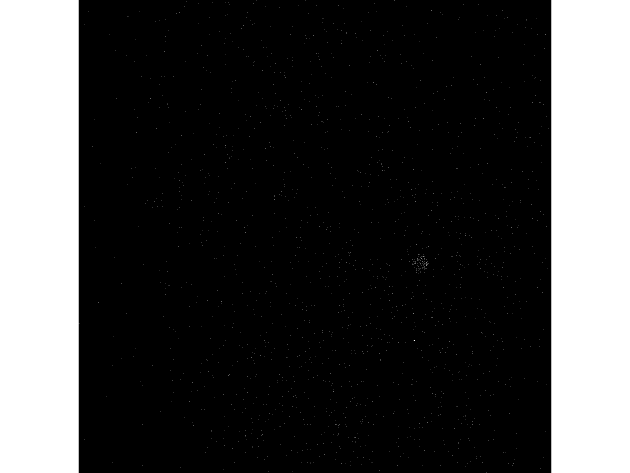

[directory,fname,fext] = fileparts(filepath);
refImg = pick_initial_reference(frames);
utils.tiff_save(refImg, ...
    fullfile(directory, strcat(fname,'_single' ,fext)));
figure;imshow(refImg,[])

function refImg = pick_initial_reference(frames)
    % 挑选最相关的一帧图片
    % Computes the initial reference image from a set of frames
    % The input frames should be in the format Ly x Lx x nFrames
    
    % Get the dimensions of the input frames
    [Ly, Lx, nFrames] = size(frames);
    
    % Reshape and zero-center the frames
    reshapedFrames = single(reshape(frames, [], nFrames)');
    reshapedFrames = reshapedFrames - mean(reshapedFrames, 2);
    
    % Compute the normalized cross-correlation matrix
    ccMatrix = reshapedFrames * reshapedFrames';
    normCCMatrix = ccMatrix ./ (sqrt(diag(ccMatrix)) * sqrt(diag(ccMatrix))');
    
    % Find the frame with the highest average correlation
    numMatches = 19;
    CCsort = sort(normCCMatrix, 2, 'descend');
    bestCC = mean(CCsort(:, 2:(numMatches+1)), 2);
    [~, bestFrameIdx] = max(bestCC);
    
    % Select the top correlated frames
    [~, indsort] = sort(normCCMatrix(bestFrameIdx, :), 'descend');
    selectedFrameIndices = indsort(1:(numMatches+1));
    
    % Compute the reference image as the mean of the selected frames
    refImg = reshapedFrames(indsort(1), :);
    refImg = reshape(refImg, Ly, Lx);
    refImg = int16(refImg);
end
